# Test Stand Structure Calculator

Written by Noah Damery, Spring 2025

The equations below mostly use the derivation for a scalar version of this problem. Aerospace majors learn the vector version in Structures 1, and after covering that content I updated this program to use the vectors version (which actually turns out to be less conservative in our case). For additional reference on this type of problem, see 12.4.4 of the 4th edition of Aircraft Structures for Engineering Students by T.H.G. Megson, which is available online and in print through the S&T Library.

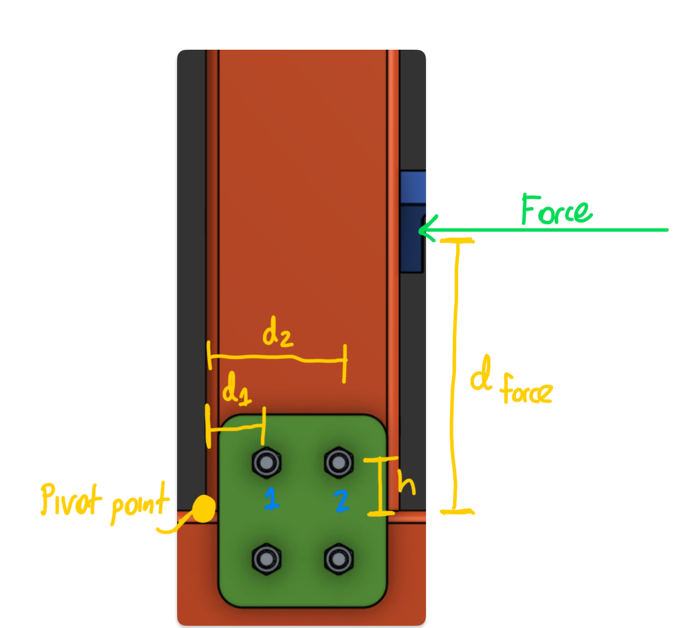

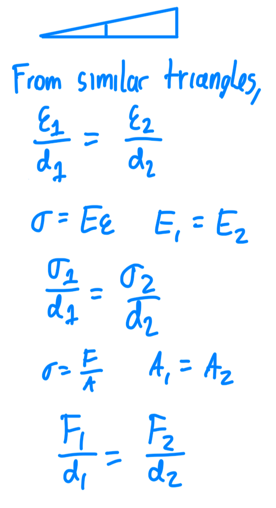

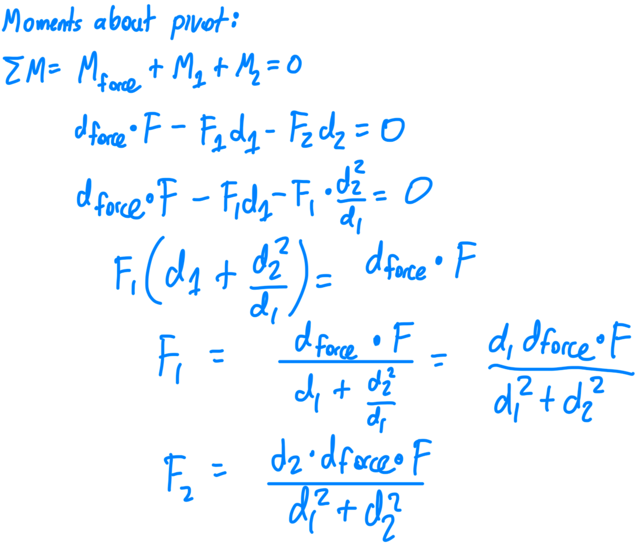

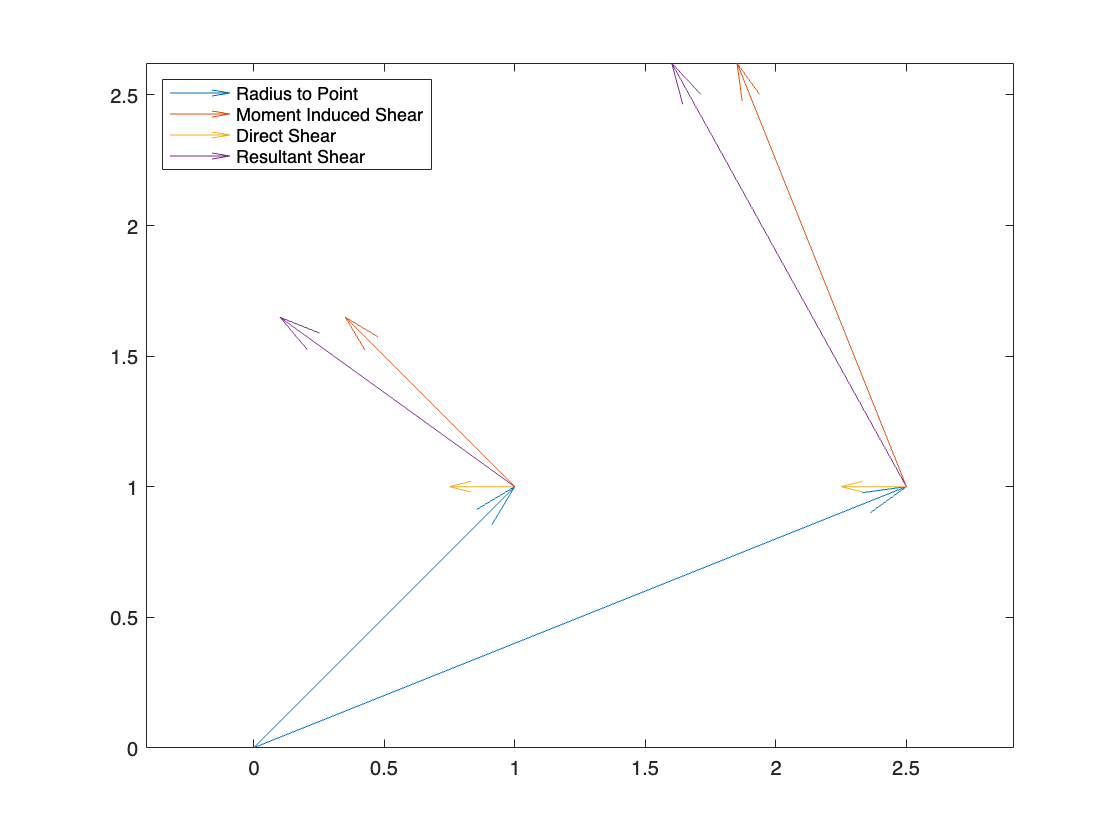

clc;
clear;
close all;


force    = 1000/1000; % kips
d_force  = 6; % in
d1       = 1; % in
d2       = 2.5; % in
h        = 1; % in

t_gusset = 0.25; % in
t_spar   = 0.1875; % in

hole_dia = 0.375; % in

bolt_shear_strength   = 44; % ksi
spar_bearing_strength = 69.6; % ksi

r1 = [d1; h];
r2 = [d2; h];

rotate90 = [0, -1; 1, 0];

f1_pr = r1*d_force*force/(norm(r1)^2+norm(r2)^2); % kips
f2_pr = r2*d_force*force/(norm(r1)^2+norm(r2)^2); % kips

f1_vec = rotate90*f1_pr;
f2_vec = rotate90*f2_pr;

shear1 = [-force/4; 0];
shear2 = [-force/4; 0];

f1_total = f1_vec + shear1;
f2_total = f2_vec + shear2;

quiver([0,0],[0,0],[r1(1), r2(1)], [r1(2), r2(2)], 'off');
hold on
quiver([r1(1), r2(1)], [r1(2), r2(2)], [f1_vec(1), f2_vec(1)], [f1_vec(2), f2_vec(2)], 'off');
quiver([r1(1), r2(1)], [r1(2), r2(2)], [shear1(1), shear2(1)], [shear1(2), shear2(2)], 'off');
quiver([r1(1), r2(1)], [r1(2), r2(2)], [f1_total(1), f2_total(1)], [f1_total(2), f2_total(2)], 'off');
axis equal

legend('Radius to Point', 'Moment Induced Shear', 'Direct Shear', 'Resultant Shear', 'Location','northwest')


f1 = norm(f1_vec);
f2 = norm(f2_vec);

% Two shear planes --------------------------v
bearing_stress_1 = f1/(hole_dia*t_spar)    / 2; % ksi
shear_stress_1   = f1/(.25*pi*hole_dia^2)  / 2; % ksi

bearing_stress_2 = f2/(hole_dia*t_spar)    / 2; % ksi
shear_stress_2   = f2/(.25*pi*hole_dia^2)  / 2; % ksi

showFOS("Hole 1 Bearing", spar_bearing_strength, bearing_stress_1, 'ksi');

Hole 1 Bearing            	Stress: 6.5 ksi 	FOS: 10.67

showFOS("Bolt 1 Shear", bolt_shear_strength, shear_stress_1, 'ksi');

Bolt 1 Shear              	Stress: 4.2 ksi 	FOS: 10.60


showFOS("Hole 2 Bearing", spar_bearing_strength, bearing_stress_2, 'ksi');

Hole 2 Bearing            	Stress: 12.4 ksi 	FOS: 5.60

showFOS("Bolt 2 Shear", bolt_shear_strength, shear_stress_2, 'ksi');

Bolt 2 Shear              	Stress: 7.9 ksi 	FOS: 5.56